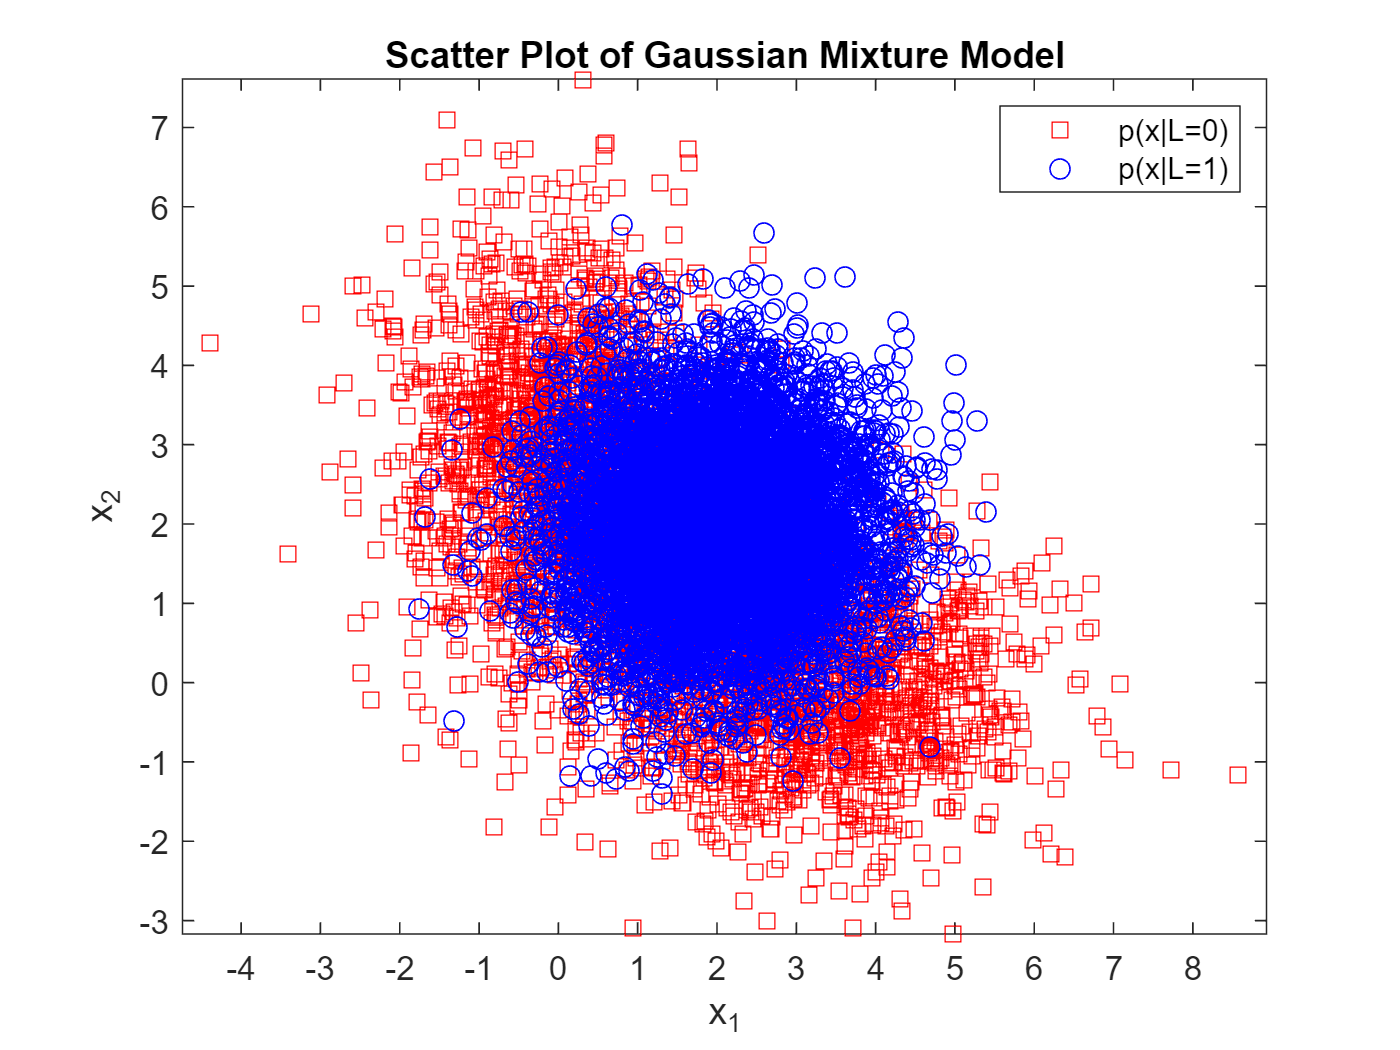

% Expected risk minimization with C classes
clear all, close all,

% Indicate if you want visualization plots
visualizationFlag = 1;% 0: no plots, 1: visualization plots

C = 2; % Number of classes
M = 3; % Number of Gaussian components
N = 10000; % Number of samples
n = 2; % Data dimensionality (must be 2 for plots to work)

% Specify loss-matrix for ERM classifier design
lossMatrix = ones(C,C)-eye(C); % Using 0-1 loss to minimize probability-of-error

% Specify the data pdf
gmmParameters.component4label = [1,1,2]; % This row vector indicates which Gaussian component belongs to which class
gmmParameters.componentWeights = [1/2, 1/2];
gmmParameters.priors = [0.65/2,0.65/2, 0.35]; % uniform component priors
gmmParameters.meanVectors = [3, 0, 2; 0, 3, 2]; % arbitrary mean vectors
gmmParameters.numberOfClasses = C;
gmmParameters.covarMatrices(:,:,1) = [2,0;0,1]; % Covariance matrices C01 for Class 0 component
gmmParameters.covarMatrices(:,:,2) = [1,0;0,2]; % Covariance matrices C01 for Class 0 component
gmmParameters.covarMatrices(:,:,3) = [1,0;0,1]; % Covariance matrices C01 for Class 0 component

% Generate samples from specified data pdf
[x,trueLabels] = HW2gmmData2D(N,gmmParameters); % Generate data

trueLabels = trueLabels+1;
% Convert component labels to class labels for each sample
labels = zeros(1,N);
for m = 1:M
    indm = find(trueLabels == m);
    labels(1,indm) = repmat(gmmParameters.component4label(m),1,length(indm));
end

% Determine ERM decisions for each samples using specified (true) data PDF
for l = 1:C
    components{l} = find(gmmParameters.component4label==l);
    classPriors(l,1) = sum(gmmParameters.priors(components{l}));
    tempP = gmmParameters.priors(components{l})/classPriors(l,1);
    tempMU = gmmParameters.meanVectors(:,components{l})';
    tempSIGMA = gmmParameters.covarMatrices(:,:,components{l});
    classConditionalPDF{l} = gmdistribution(tempMU,tempSIGMA,tempP);
end
[n,N] = size(x);
% Evaluate class conditional likelihoods p(x|L=l) for each sample-label pair.
for l = 1:C
    %pxgivenl(l,:) = evalGaussianPDF(x,gmmParameters.meanVectors(:,l),gmmParameters.covMatrices(:,:,l)); 
    pxgivenl(l,:) = pdf(classConditionalPDF{l},x');
end
%determine the overall data pdf
classConditionalPDFTotal = gmdistribution(gmmParameters.meanVectors',gmmParameters.covarMatrices,gmmParameters.priors);

% Evaluate the likelihood of each sample according to the overall data pdf
%px=classPriors'*pxgivenl;
px = pdf(classConditionalPDFTotal,x')';%pdf(gmmParameters,x); % Note that gmmParameters is a mixture of class-conditional GMMs
% Evaluate the class posterior probabilities for each label-sample pair
classPosteriors = pxgivenl.*repmat(classPriors,1,N)./repmat(px,C,1); % P(L=l|x)
% Evaluate expected risk (loss) values for each decision-sample pair
expectedRisks = lossMatrix*classPosteriors; % Expected Risk for each label (rows) for each sample (columns)
% Determine minimum-expected-risk decisions for each sample
[~,decisions] = min(expectedRisks,[],1); 
[roc_X,roc_Y] = perfcurve(trueLabels,decisions,2)

roc_X =          0
    0.1223
    1.0000


roc_Y =          0
    0.7395
    1.0000


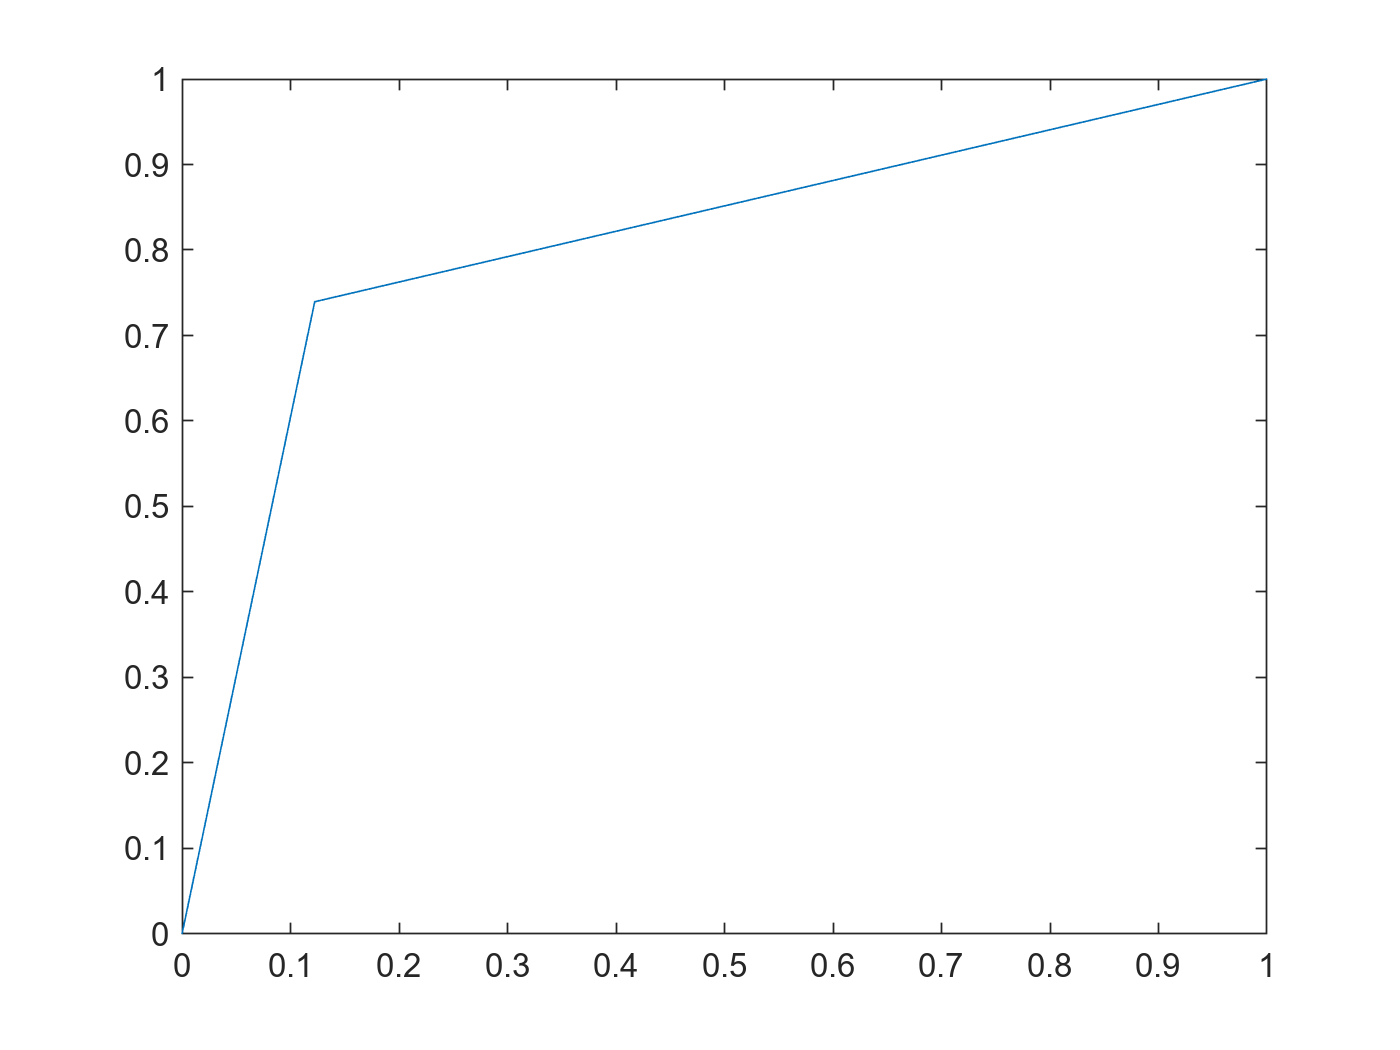

figure, plot(roc_X,roc_Y)

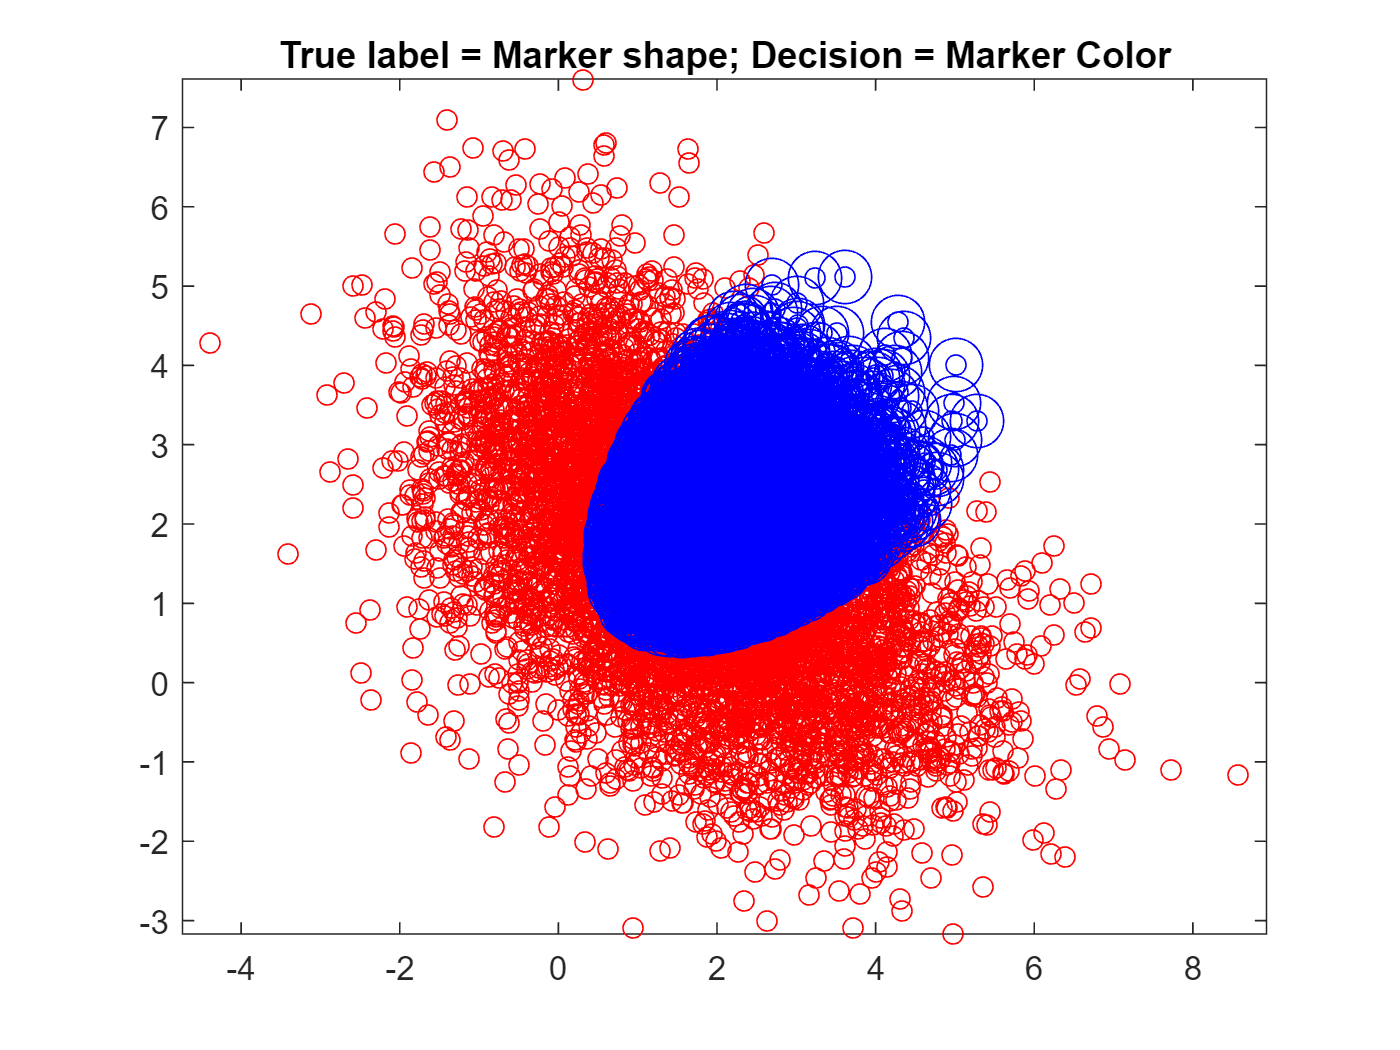

% Note: minimum expected risk decision with 0-1 loss is MAP classification
% and minimizes probability of error

% Estimate the confusion matrix P(D=d|L=l) from samples for each
% decision-label pair
mShapes = 'ox'; % Accomodates up to C=5
mColors = 'rb';
if visualizationFlag==1 & 0<n & n<=3
    figure(1), clf,
end 
for d = 1:C % each decision option
    for l = 1:C % each class label
        ind_dl = find(decisions==d & labels==l);
        confusionMatrix(d,l) = length(ind_dl)/length(find(labels==l));
        if visualizationFlag==1 & 0<n & n<=3
            figure(1), 
            plot(x(1,ind_dl),x(2,ind_dl),strcat(mShapes(l),mColors(d))), 
            hold on, axis equal,
            title('True label = Marker shape; Decision = Marker Color')
            if d~=l
                plot(x(1,ind_dl),x(2,ind_dl),strcat(mShapes(l),mColors(d)),'Markersize',16),
            end
        end
    end
end

% Second example: C=2, p(x|L=1) has GMM with 2 components, p(x|L=2) has GMM
% with 3 components